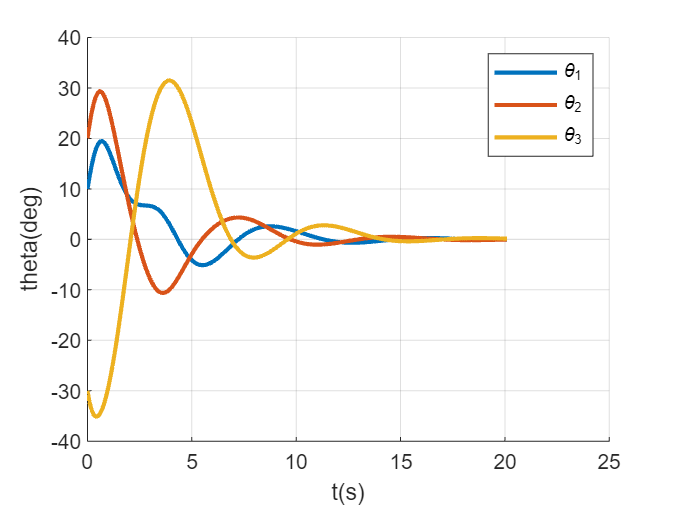

%% 初始参数设置
close all,clear,clc,
tic,

global J1 J2 J3 f1 f2 f3;
J1 = 1000;  J2 = 1500;  J3 = 1800;
f1 = 200;   f2 = 300;   f3 = 360;

% 初始化参数
t0 = 0.0;
dt = 0.1;
tf = 20.0;
tout = t0:dt:tf;

theta1 = deg2rad(10);
theta2 = deg2rad(20);
theta3 = deg2rad(-30);
omega1 = deg2rad(10);
omega2 = deg2rad(20);
omega3 = deg2rad(-30);
state = [theta1;theta2;theta3;omega1;omega2;omega3];
stateout = state;
uout = []; % 控制方程u
eta1 = 0;
eta2 = 0;
eta3 = 0;

theta1_deg = 10;
theta2_deg = 20;
theta3_deg = -30;
theta1_deg_out = theta1_deg;
theta2_deg_out = theta2_deg;
theta3_deg_out = theta3_deg;

% PID参数设置
kp1 = -1000;    kd1 = -1000;    ki1 = -300;%-0.1;
kp2 = -1500;    kd2 = -1500;    ki2 = -500;%-0.1;
kp3 = -1800;    kd3 = -1800;    ki3 = -500;%-0.1;

% 设置曲线标签
le_str_M = {"M_1", "M_2", "M_3"};
le_str_theta = {"\theta_1", "\theta_2", "\theta_3"};

%% 仿真
% 迭代
for t=t0:dt:tf
    M1 = kp1*theta1 + kd1*omega1 + ki1*eta1;
    M2 = kp2*theta2 + kd2*omega2 + ki2*eta2;
    M3 = kp3*theta3 + kd3*omega3 + ki3*eta3;
    u = [M1;M2;M3];
    uout = [uout, u];

    % 迭代方程组
    ke1 = statequation(t, state, u);
    ke2 = statequation(t+0.5*dt, state+0.5*ke1*dt, u);
    ke3 = statequation(t+0.5*dt, state+0.5*ke2*dt, u);
    ke4 = statequation(t+dt, state+ke3*dt, u);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];

    % 状态变量更新
    theta1 = state(1);
    theta2 = state(2);
    theta3 = state(3);
    omega1 = state(4);
    omega2 = state(5);
    omega3 = state(6);
    eta1 = eta1 + theta1 * dt;
    eta2 = eta2 + theta2 * dt;
    eta3 = eta3 + theta3 * dt;

    theta1_deg = theta1 / pi * 180;
    theta2_deg = theta2 / pi * 180;
    theta3_deg = theta3 / pi * 180;
    theta1_deg_out = [theta1_deg_out, theta1_deg];
    theta2_deg_out = [theta2_deg_out, theta2_deg];
    theta3_deg_out = [theta3_deg_out, theta3_deg];
end

theta1out = stateout(1, :);
theta2out = stateout(2, :);
theta3out = stateout(3, :);
omega1out = stateout(4, :);
omega2out = stateout(5, :);
omega3out = stateout(6, :);

% 循环最后一次更新
tout = [tout, tout(end)+dt];
M1 = kp1*theta1 + kd1*omega1 + ki1*eta1;
M2 = kp2*theta2 + kd2*omega2 + ki2*eta2;
M3 = kp3*theta3 + kd3*omega3 + ki3*eta3;
u = [M1;M2;M3];
uout = [uout, u];

M1out = uout(1, :);
M2out = uout(2, :);
M3out = uout(3, :);

% 画图
figure(1);
hold on;grid on;
plot(tout, theta1_deg_out, 'LineWidth', 2);
plot(tout, theta2_deg_out, 'LineWidth', 2);
plot(tout, theta3_deg_out, 'LineWidth', 2);
xlabel('t(s)');ylabel('theta(deg)')
legend("\theta_1", "\theta_2", "\theta_3");

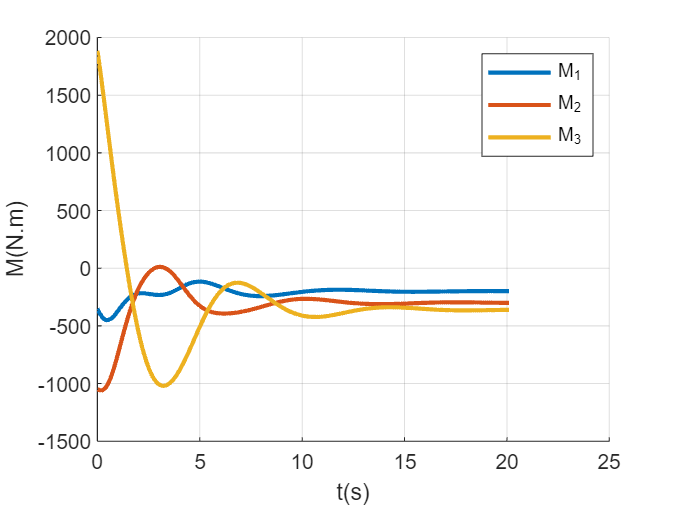


figure(2);
hold on;grid on;
plot(tout, M1out, 'LineWidth', 2);
plot(tout, M2out, 'LineWidth', 2);
plot(tout, M3out, 'LineWidth', 2);
xlabel('t(s)');ylabel('M(N.m)');
legend("M_1", "M_2", "M_3");


toc,

历时 0.120642 秒。



%% 函数

function output=statequation(t, state, u)
global J1 J2 J3 f1 f2 f3;  % 转动惯量
% state = [theta1,theta2,theta3,w1,w2,w3]
% 获取此刻状态
theta1 = state(1);
theta2 = state(2);
theta3 = state(3);
omega1 = state(4);
omega2 = state(5);
omega3 = state(6);
M1 = u(1);
M2 = u(2);
M3 = u(3);

% 计算导数。作为状态输出
theta1dot = omega1 - omega2*cos(theta1)*tan(theta3) + omega3*sin(theta1)*tan(theta3);
theta2dot = omega2*cos(theta1)/cos(theta3) - omega3*sin(theta1)/cos(theta3);
theta3dot = omega2*sin(theta1) + omega3*cos(theta1);
omega1dot = (J2-J3)/J1*omega2*omega3 + (M1+f1)/J1;
omega2dot = (J3-J1)/J2*omega1*omega3 + (M2+f2)/J2;
omega3dot = (J1-J2)/J3*omega1*omega2 + (M3+f3)/J3;

output = [theta1dot;theta2dot;theta3dot;omega1dot;omega2dot;omega3dot];
end